# 2018 - CAB420 - Machine Learning

Group Assignment 1 Alex Wilson and Christopher Ayling

## Theory

Logistic regression is a method of fitting a probabilistic classifier that gives soft linear thresh-olds. It is common to use logistic regression with an objective function consisting of the negative log probability of the data plus an L2 regularizer:


$$L(\textbf{w}) = -\displaystyle\sum_{i=1}^{N} Log \left( \frac{1}{1+e^{y_i \left( \textbf{w}^T \textbf{x}_i + b \right) }} \right) + \lambda \|\textbf{w}\|_2^2 $$


(a) Find the partial derivatives $\frac{\partial L}{\partial w_j}$


$$ u = 1 + e^{y_i \left( \textbf{w}^T \textbf{x} + b \right)} $$



$$ L(\textbf{w}) = -\displaystyle\sum_{i=1}^{N} -log(u) + \lambda \|\textbf{w}\|_2^2 $$



$$ \frac{\partial L}{\partial \textbf{w}_j} = -\displaystyle\sum_{i=1}^{N} \frac{\partial}{\partial u} - log(u) \frac{\partial u}{\partial \textbf{w}_j} +  \frac{\partial}{\partial \textbf{w}_j} \lambda \|\textbf{w}\|_2^2 $$



$$ \frac{\partial}{\partial w_j} \lambda \|\textbf{w}\|_2^2 = 2 \lambda \textbf{w}_j $$



$$ \frac{\partial}{\partial u} -log(u) = \frac{-1}{u} $$



$$ \frac{\partial u }{\partial \textbf{w}_j} = y_i \textbf{x}_i e^{y_i(\textbf{w}^T \textbf{x}_i + b)} $$



$$ \frac{\partial L}{\partial \textbf{w}_j} = -\displaystyle\sum_{i=1}^{N} 2 \lambda \textbf{w}_j - \frac{y_i \textbf{x}_i e^{y_i(\textbf{w}^T _i + b)}}{1 + e^{y_i \left( \textbf{w}^T \textbf{x}_i + b \right)}} $$


(b) Find the partial second derivatives $\frac{\partial L^2}{\partial w_j \partial w_k}$


$$H_{L\left(w\right)} =\left\lbrack \begin{array}{c}
\frac{\partial^2 L}{\partial w_j \partial w_j } & \frac{\partial^2 L}{\partial w_j \partial w_k }\\
\frac{\partial^2 L}{\partial w_k \partial w_j } & \frac{\partial^2 L}{\partial w_k \partial w_k }
\end{array}\right\rbrack$$


(c) From these results, show that $L(w)$ is a convex function.

## 1. Feature, Classes and Linear Regression

(a) Plot the training data in a scatter plot.

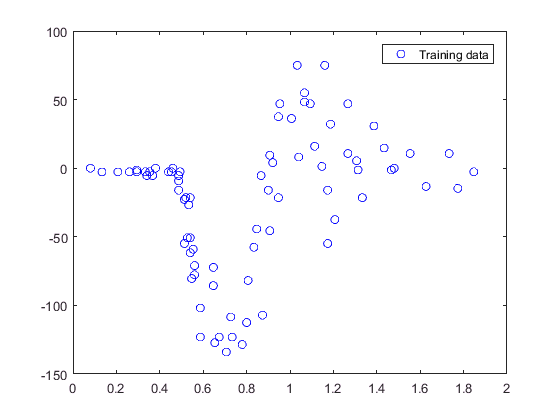

%Clean up
clc
clear
close all
%Load in and set up variables
mTrain = load('data/mcycleTrain.txt');
ytr = mTrain(:,1); 
xtr = mTrain(:,2);
%Plot the training data
plot(xtr, ytr, 'bo');
hold on;
legend('Training data');

(b) Create a linear predictor (slope and intercept) using the above functions. Plot it on the same plot as the training data.

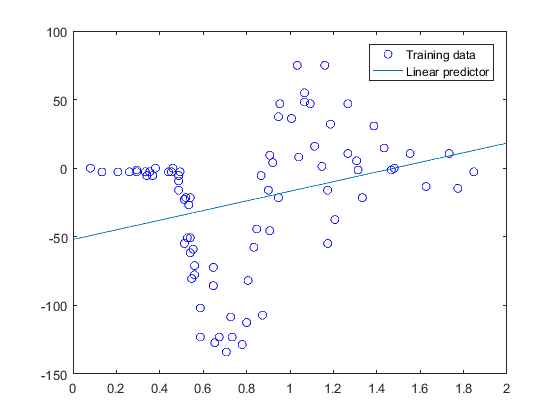

linXtr = polyx(xtr, 1);
linLearner = linearReg(linXtr, ytr);
xline = [0:.01:2]';
yline = predict(linLearner, polyx(xline, 1));
plot(xline, yline);
legend('Training data', 'Linear predictor');

(c) Create another plot with the data and a fifth-degree polynomial

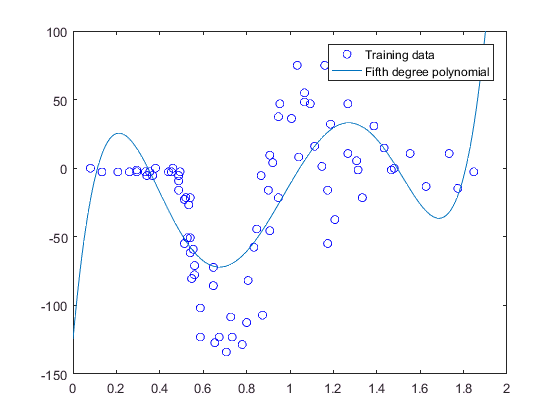

figure;
plot(xtr, ytr, 'bo');
hold on;
fifthXtr = polyx(xtr, 5);
fifthLearner = linearReg(fifthXtr, ytr);
xline = [0:.01:2]';
yline = predict(fifthLearner, polyx(xline, 5));
plot(xline, yline);
legend('Training data', 'Fifth degree polynomial');
axis([0 2 -150 100]);

(d) Calculate the mean squared error associated with each of your learned models on the training data.

training_MSE_of_linear_predictor = mse(linLearner, linXtr, ytr)

training_MSE_of_linear_predictor = 2.2708e+03

training_MSE_of_fifth_degree_predictor = mse(fifthLearner, fifthXtr, ytr)

training_MSE_of_fifth_degree_predictor = 1.2546e+03

(e) Calculate the MSE for each model on the test data (in mcycleTest.txt).

mTest = load('data/mcycleTest.txt');
ytst = mTest(:,1);
xtst = mTest(:,2);
linXtst = polyx(xtst, 1);
fifthXtst = polyx(xtst, 5);

test_MSE_of_linear_predictor = mse(linLearner, linXtst, ytst)

test_MSE_of_linear_predictor = 1.7049e+03

test_MSE_of_fifth_degree_predictor = mse(fifthLearner, fifthXtst, ytst)

test_MSE_of_fifth_degree_predictor = 999.6535

## 2. kNN Regression

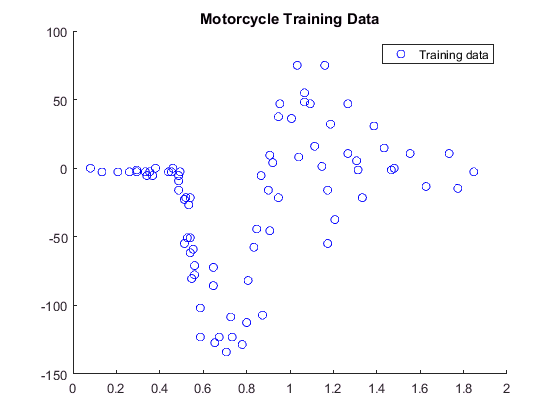

clc
clear
% Load train data
mTrain = load('mcycleTrain.txt');
Ytrain = mTrain(:,1);
Xtrain = mTrain(:,2);
% Load test data
mTest = load('mcycleTest.txt');
Ytest = mTest(:,1);
Xtest = mTest(:,2);
% Plot Training Data
figure('name', 'Motorcycle Data');
hold on
plot(Xtrain, Ytrain, 'bo');
title('Motorcycle Training Data')
legend('Training data');
hold off

(a) Using the knnRegress class, implement (add code to) the predict function to make it functional.

<include>@knnRegress/predict.m</include>

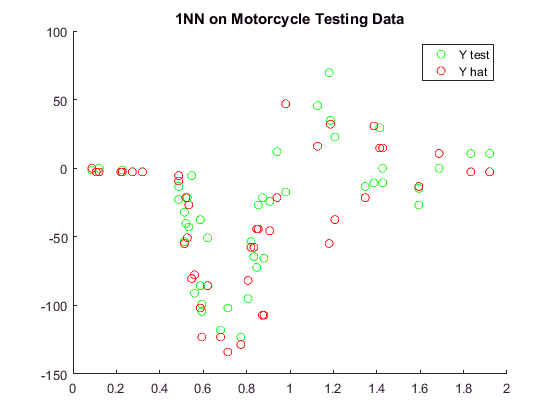

learner = knnRegress(1,Xtrain, Ytrain);
Yhat = predict(learner, Xtest);
figure('name', 'Knn Testing');
hold on
plot(Xtest, Ytest, 'go');
plot(Xtest, Yhat, 'ro');
legend('Y test', 'Y hat');
title('1NN on Motorcycle Testing Data')
hold off

(b) Using the same technique as in Problem 1a, plot the predicted function for several values of $k: 1, 2, 3, 5, 10, 50$. How does the choice of $k$ relate to the “complexity” of the regression function?

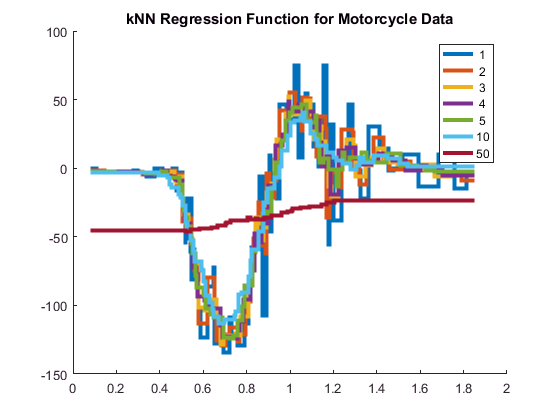

%
% The higher the value of K, the lower the complexity.
%
ks = [1, 2, 3, 4, 5, 10, 50];
Xs = min(Xtrain):0.001:max(Xtrain); Xs = Xs';
figure('name', 'testing values of k')
hold on
learner = knnRegress(1,Xtrain, Ytrain);
for i=1:length(ks)
    learner = knnRegress(ks(i),Xtrain, Ytrain);
    stairs(Xs, predict(learner, Xs), '-', 'linewidth', 3);
end
title('kNN Regression Function for Motorcycle Data')
legend(cellstr(int2str(ks')))
hold off

(c) What kind of functions can be output by a nearest neighbor regression function? Briefly justify your conclusion.

As a KNN regression produces a piecewise linear function, given the right data, any function can be approximated.

## 3. Hold-out and Cross-validation

(a) Similarly to Problem 1 and 2, compute the MSE of the test data on a model trained on only the first 20 training data examples for $k = 1, 2, 3, . . . , 100$. Plot the MSE versus $k$ on a log-log scale (see help loglog).

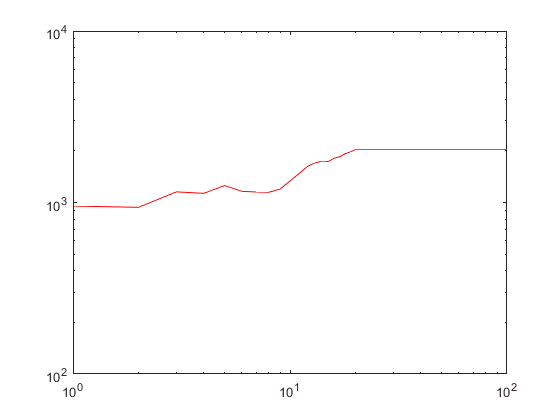

%Clean up
clc
clear
close all
%Import data
mTrain = load('data/mcycleTrain.txt');
mTest = load('data/mcycleTest.txt');
ytst = mTest(:,1); %  testing data 
xtst = mTest(:,2);

ytr = mTrain(1:20,1); % first 20 training data examples
xtr = mTrain(1:20,2);
MSE1 = zeros(100, 1); % initalise a vector for MSE of each k value

for k=1:100 % iterate on each k value
    learner = knnRegress(k, xtr, ytr); % create the learner using k
    yhat = predict(learner, xtst); % predict and find MSE relative to test data
    MSE1(k) = mean((yhat - ytst).^2);
end 
figure;
loglog(1:100, MSE1, 'r'); % plot on a loglog graph
hold on;

(b) Repeat, but use all the training data. What happened? Contrast with your results from problem 1 (hint: which direction is “complexity” in this picture?).

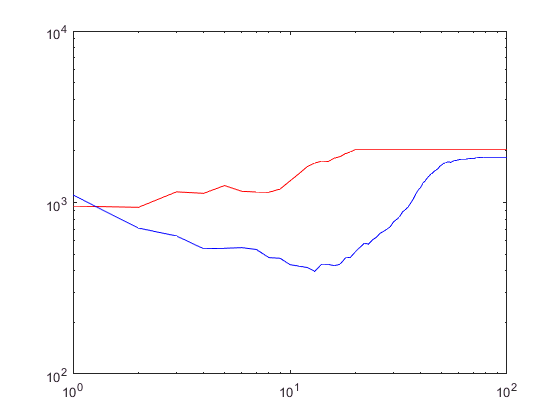

ytr = mTrain(:,1); % all training data examples
xtr = mTrain(:,2);
MSE2 = zeros(100, 1); % initalise a vector for MSE of each k value

for k=1:100 % iterate on each k value
    learner = knnRegress(k, xtr, ytr); % create the learner using k
    yhat = predict(learner, xtst); % predict and find MSE relative to test data
    MSE2(k) = mean((yhat - ytst).^2);
end 

loglog(1:100, MSE2, 'b'); % plot on the loglog graph

(c) Using only the training data, estimate the curve using 4-fold cross-validation. Split the training data into two parts, indices 1:20 and 21:80; use the larger of the two as training data and the smaller as testing data, then repeat three more times with different sets of 20 and average the MSE. Add this curve to your plot. Why might we need to use this technique?

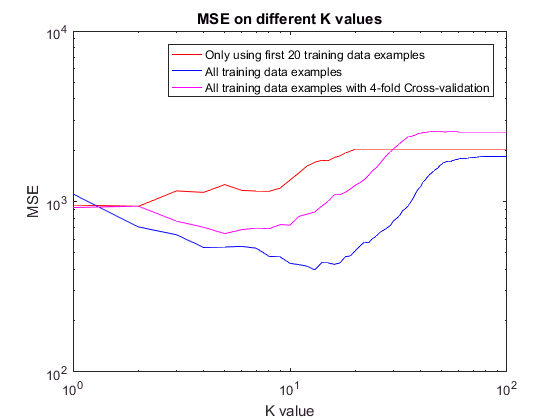

MSE3 = zeros(100, 1); % initalise a vector for MSE of each k value
for k=1:100 % test for 100 values of k
    MSEtemp = zeros(4, 1); % temp mse array for each i (averaged for each k)
    for i=1:4
        m = i*20; n = m-19; % local bounds
        iTest = mTrain(n:m,:); % 20 indicies for testing
        iTrain = setdiff(mTrain, iTest, 'rows'); % rest for training
        learner = knnRegress(k, iTrain(:,2), iTrain(:,1)); % train the learner
        yhat = predict(learner, iTest(:,2)); % predict at testing x values
        MSEtemp(i) = mean((yhat - iTest(:,1)).^2); 
    end
    MSE3(k) = mean(MSEtemp); % average the MSE 
end
loglog(1:100, MSE3, 'm'); % plot on the loglog graph
% Figure beautification
xlabel('K value');
ylabel('MSE');
legend('Only using first 20 training data examples', ...
    'All training data examples', ...
    'All training data examples with 4-fold Cross-validation');
title('MSE on different K values');

## 4. Nearest Neighbor Classifiers

clc
clear
% Load Iris Dataset
iris = load('iris.txt');
pi = randperm(size(iris, 1));
Y = iris(pi, 5);
X = iris(pi, 1:2);
m = length(Y);

(a) Plot the data by their feature values, using the class value to select the color.

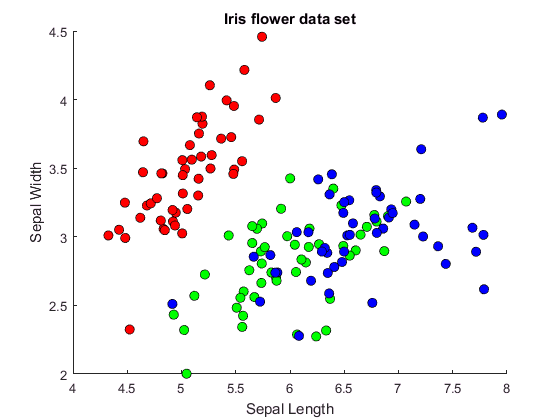

figure('name', 'Iris Flowers')
title('Iris flower data set')
xlabel('Sepal Length')
ylabel('Sepal Width')
hold on
plot(X(Y==0,1), X(Y==0,2), 'ko', 'markersize',7, 'markerfacecolor', 'red');
plot(X(Y==1,1), X(Y==1,2), 'ko', 'markersize',7, 'markerfacecolor', 'green');
plot(X(Y==2,1), X(Y==2,2), 'ko', 'markersize',7, 'markerfacecolor', 'blue');
hold off

(b) Use the provided knnClassify class to learn a 1-nearest-neighbor predictor.

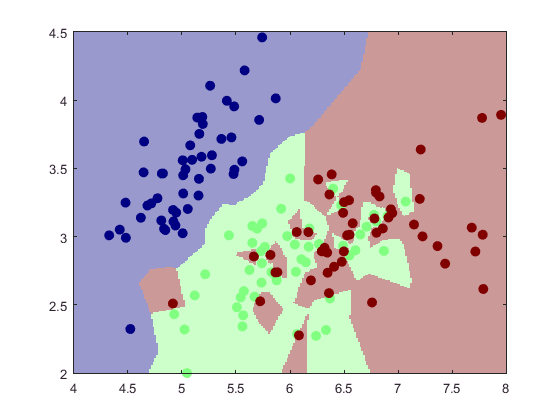

nnlearner = knnClassify(1, X, Y);
class2DPlot(nnlearner, X, Y);

(c) Do the same thing for several values of k (say, [1, 3, 10, 30]) and comment on their appearance.

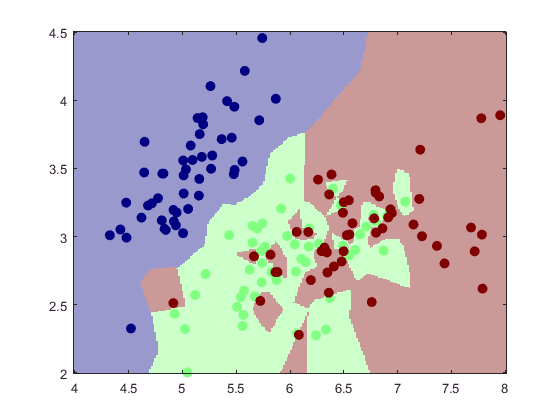

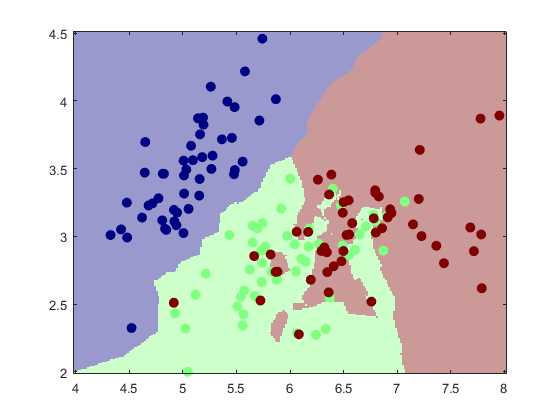

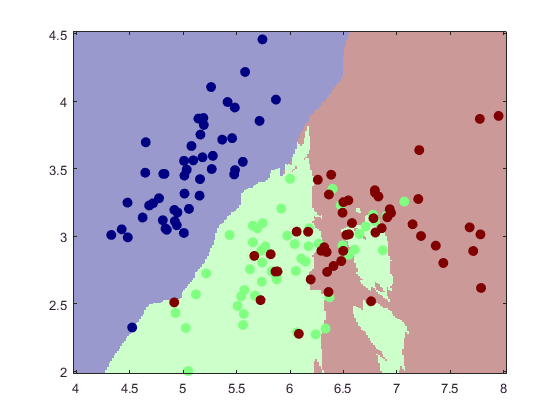

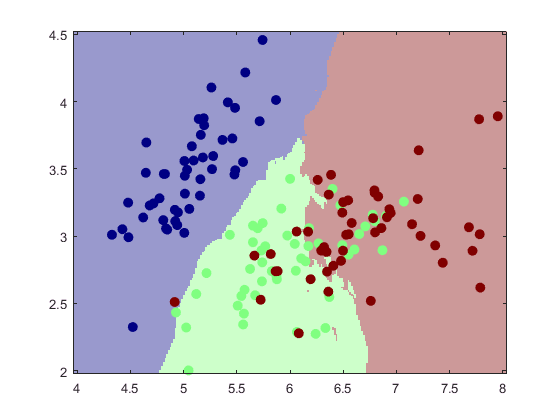

ks = [1, 3, 10, 30];
for i=1:length(ks)
    learner = knnClassify(ks(i), X, Y);
    class2DPlot(learner, X, Y);
end

(d) Now split the data into an 80/20 training/validation split. For $k = [1, 2, 5, 10, 50, 100, 200]$, learn a model on the 80% and calculate its performance (# of data classified incorrectly) on the validation data. What value of k appears to generalize best given your training data? Comment on the performance at the two endpoints, in terms of over- or under-fitting.

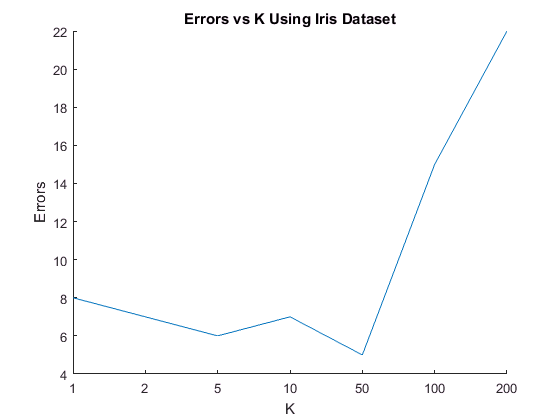

split = 0.8; train_size = floor(split*m);

Xtrain = X(1:train_size,:);
Ytrain = Y(1:train_size,:);
Xtest = X(train_size+1:end,:);
Ytest = Y(train_size+1:end,:);

ks = [1, 2, 5, 10, 50, 100, 200];
errors = [];
for i=1:length(ks)
    learner = knnClassify(ks(i), Xtrain, Ytrain);
    Yhat = predict(learner, Xtest);
    errors = [errors, sum(Yhat ~= Ytest)];
end
figure('name', 'Errors vs K');
hold on
title('Errors vs K Using Iris Dataset');
xlabel('K');
ylabel('Errors');
plot(errors);
xticklabels(ks)
hold off

## 5. Perceptron and Logistic Regression

(a) Show the two classes in a scatter plot and verify that one is linearly separable while the other is not

(b) Write (fill in) the function @logisticClassify2/plot2DLinear.m so that it plots the two classes of data in di?erent colors, along with the decision boundary (a line). Include the listing of your code in your report. To demo your function plot the decision boundary corresponding to the classifier $$ sign(.5 + 1x_1 - .25x_2) $$

(c) Complete the predict.m function to make predictions for your linear classifier.

(d)


$$ \sigma\left( 1 + exp(-z) \right)^{-1} $$



$$ J_j(\theta) = -y^{j} \log \sigma \left( \theta x^{(j)T} \right) -(1-y^{(j)}) \log \left( 1-\sigma \left( \theta x^{(j)T} \right) \right) + \alpha \displaystyle\sum_i \theta_i^2 $$


Derive the gradient of the regularized negative log likelihood $J_j$ for logistic regression, and give it in your report

(e) Complete your train.m function to perform stochastic gradient descent on the logistic loss function. 

(1) computing the surrogate loss function at each iteratio

(2) computing the prediction and gradient associated with each data poin

(3) a gradient step on the parameters $\theta$

(4) a stopping criterion.

(f) Run your logistic regression classifier on both data sets (A and B); for this problem, use no regularization $(\alpha = 0)$. Describe your parameter choices (stepsize, etc.) and show a plot of both the convergence of the surrogate loss and error rate, and a plot of the final converged classifier with the data (using e.g. plotClassify2D). In your report, please also include the functions that you wrote (at minimum, train.m,

%but possibly a few small helper functions as well)

close all